## Paramètre q sous Mesure Neutre Q

Pour commencer, on extrait la valeur de $ \(q\)$ - dividendes sous la mesure Q. Ce paramètre n'est pas estimé a partir des dividendes historiques, mais extrait de manière implicite a partir des prix d'options via la parité put-call. Il s'agit donc d'un parametre de pricing sous Q, cohérent avec les prix de marche a la date de calibration. 

La date de valorisation est fixée au 2 avril 2026. Afin d'assurer la cohérence du pipeline, l'extraction de $ \(q\)$ et la calibration du modèle de Heston sont réalisées sur la même coupe de maturité, soit environ $ \(1.4136\)$ mois, avec une tolérance de $\(0.1\) $mois.

df1 = DATA_CALLS_PUTS__BLOOMBERG_2;

as_of_date = datetime(2026,4,2);
target_maturity = 11.53;   % in months
tolerance = 0.1;           
S0 = 44.29;                 % pris a partir de PX_LAST (daily data Bloomberg)
r = 0.0253;                   % pris a partir d'OIS -> voire interest_calibration

df1.ExpiryDate = datetime(string(df1.ExpiryDate), 'InputFormat','M/d/yy');

summary(df1)


df1: 172×9 table

Variables:

    Ticker: categorical (1 categories)
    ExpiryDate: datetime
    Type: categorical (2 categories)
    Strike: double
    Bid: double
    Ask: double
    Last: double
    IVM

% Date a maturite
days_to_maturity = days(df1.ExpiryDate - as_of_date);
df1.Maturity_months = days_to_maturity / 365.0 * 12;
df1.T_years = df1.Maturity_months / 12;
df1.Maturity_months

ans =    11.5397
   11.5397
   11.5397
   11.5397
   11.5397
   11.5397
   11.5397
   11.5397
   11.5397
   11.5397
   11.5397
   11.5397
   11.5397
   11.5397
   11.5397


% On filtre notre maturité visée (consistant avec la calibration Heston)
idx_target = abs(df1.Maturity_months - target_maturity) <= tolerance;
df_slice = df1(idx_target,:);

%% Mid prices 
df_slice.Mid = (df_slice.Bid + df_slice.Ask) / 2; %plus stable approx du marché comparée a l'utilisation de ask/bid

df_slice

df_slice = 32×12 table
    Ticker    ExpiryDate     Type    Strike     Bid      Ask     Last     IVM      Volm    Maturity_months    T_years     Mid 
    ______    ___________    ____    ______    _____    _____    ____    ______    ____    _______________    _______    _____

     ZCN      19-Mar-2027     C         24     20.15    20.75     0      29.032     0           11.54         0.96164    20.45
     ZCN      19-Mar-2027     C         25      19.2     19.8     0      32.009     0           11.54         0.96164     19.5
     ZCN      19-Mar-2027     C         30     14.25    14.9

df_slice.Type(1)

ans = categorical
     C 


calls = df_slice(df_slice.Type == 'C', :);
puts  = df_slice(df_slice.Type == 'P', :);


% On separe les Calls et puts
calls = calls(:, {'Strike','ExpiryDate','Mid','T_years'});
puts  = puts(:,  {'Strike','ExpiryDate','Mid'});


calls.Properties.VariableNames{'Mid'} = 'CallMid';
puts.Properties.VariableNames{'Mid'}  = 'PutMid';

%% On match les calls et puts par strike  et expiry
tbl = innerjoin(calls, puts, 'Keys', {'Strike','ExpiryDate'}); % Afin d'utiliser la parité Call-Put

Sous absence d'arbitrage, la parité put-call européenne donne $\[
C(K,T)-P(K,T)=S_0 e^{-qT}-K e^{-rT}.
\]$

En isolant $ \(q\)$, on obtient $\[
q = -\frac{1}{T}\log\!\left(\frac{C(K,T)-P(K,T)+Ke^{-rT}}{S_0}\right).
\]$

Cette relation permet d'extraire une valeur implicite de $ \(q\)$ pour chaque strike à la maturité considérée.

numerator = tbl.CallMid - tbl.PutMid + tbl.Strike .* exp(-r .* tbl.T_years);
tbl.q_implied = -(1 ./ tbl.T_years) .* log(numerator ./ S0);

%% On laisse les mêmes filtration que notre mdèle, Strike centre autour de S0
atm_idx = (tbl.Strike >= 0.80*S0) & (tbl.Strike <= 1.20*S0);
tbl_atm = tbl(atm_idx,:);

Afin d'obtenir une valeur unique, on agrège ces estimations:

La médiane est utilisée car elle est robuste aux valeurs aberrantes, qui peuvent apparaître en raison du bruit de marché, des spreads bid-ask ou d'une liquidité plus faible sur certains strikes.

q = median(tbl_atm.q_implied)

q = 0.0214

fprintf('Estimated q under Q = %.8f\n', q);

Estimated q under Q = 0.02143814


Le q obtenu de 0.02143814 est un rendement de dividende implicite sous la mesure risque-neutre Q, extrait des prix d'options via la parité put-call.

Cette valeur peut différer du rendement de dividende historique, car elle reflete un paramètre de pricing et non une moyenne des distributions passées. A titre indicatif, le rendement de dividende observé sur 12 mois pour l'ETF est d'environ 2.14% selon Bloomberg, basé sur les distributions historiques.

En particulier, a maturité courte, les dividendes étant verses de manière discrète, le rendement continu équivalent peut etre plus faible, ce qui est cohérent avec le resultat observé ici.

disp(tbl_atm(:, {'Strike','ExpiryDate','T_years','CallMid','PutMid','q_implied'}));

    Strike    ExpiryDate     T_years    CallMid    PutMid    q_implied
    ______    ___________    _______    _______    ______    _________

       36     19-Mar-2027    0.96164      8.95     0.685     0.021116 
     37.5     19-Mar-2027    0.96164     7.625     0.855     0.021861 
       38     19-Mar-2027    0.96164       7.2      0.92     0.021909 
       40     19-Mar-2027    0.96164      5.65      1.31     0.021623 
       42     19-Mar-2027    0.96164     4.175      1.72      0.02002 
     42.5     19-Mar-2027    0.96164     3.825      1.86     0.020068 
       44     19-Mar-2027    0.96164     2.885      2.38     0.019974 
       45     19-Mar-2027    0.96164     2.295      2.83     0.021507 
       46     19-Mar-2027    0.96164      1.79      3.29     0.021245 
       48     

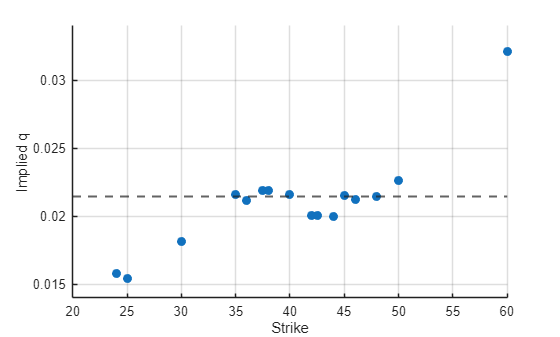


%% Optional plot
figure;
scatter(tbl.Strike, tbl.q_implied, 45, 'filled');
hold on;
yline(q, '--', 'LineWidth', 1.5);
xlabel('Strike');
ylabel('Implied q');
grid on;
hold off;